% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 36);

% Specify sheet and range
opts2.Sheet = "Planilha1";
opts2.DataRange = "A41:AJ10981";

% Specify column names and types
opts2.VariableNames = ["ScanSweepTime_Sec_", "ScanNumber", "x101Time_Sec_", "x101__C_", "x102Time_Sec_", "x102__C_", "x103Time_Sec_", "x103__C_", "x104Time_Sec_", "x104__C_", "x105Time_Sec_", "x105__C_", "x106Time_Sec_", "x106__C_", "x107Time_Sec_", "x107__C_", "x108Time_Sec_", "x108__C_", "x109Time_Sec_", "x109__C_", "x110Time_Sec_", "x110__C_", "x111Time_Sec_", "x111__C_", "x112Time_Sec_", "x112__C_", "x113Time_Sec_", "x113__C_", "x114Time_Sec_", "x114__C_", "x115Time_Sec_", "x115__C_", "x116Time_Sec_", "x116__C_", "x117Time_Sec_", "x117_Vac_"];
opts2.VariableTypes = ["datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double"];

% Import the data
data = readtimetable("C:\Users\anton\Desktop\Insper\2024.2\TransCal\TransCal_Projeto1\data.xlsx", opts2, "UseExcel", false, "RowTimes", "ScanSweepTime_Sec_");

% Clear temporary variables
clear opts2

% Display results
data

data = 10941×35 timetable
     ScanSweepTime_Sec_     ScanNumber       x101Time_Sec_        x101__C_       x102Time_Sec_        x102__C_       x103Time_Sec_        x103__C_       x104Time_Sec_        x104__C_       x105Time_Sec_        x105__C_       x106Time_Sec_        x106__C_       x107Time_Sec_        x107__C_       x108Time_Sec_        x108__C_       x109Time_Sec_        x109__C_       x110Time_Sec_        x110__C_       x111Time_Sec_        x111__C_       x112Time_Sec_        x112__C_       x113Time_Sec_        x113__C_<

% Gráfico 1.1
time = data.x101Time_Sec_

time = 10941×1 datetime array
   16-Sep-2024 08:32:41
   16-Sep-2024 08:32:51
   16-Sep-2024 08:33:01
   16-Sep-2024 08:33:11
   16-Sep-2024 08:33:21
   16-Sep-2024 08:33:31
   16-Sep-2024 08:33:41
   16-Sep-2024 08:33:51
   16-Sep-2024 08:34:01
   16-Sep-2024 08:34:11
   16-Sep-2024 08:34:21
   16-Sep-2024 08:34:31
   16-Sep-2024 08:34:41
   16-Sep-2024 08:34:51
   16-Sep-2024 08:35:01
   16-Sep-2024 08:35:11
   16-Sep-2024 08:35:21
   16-Sep-2024 08:35:31
   16-Sep-2024 08:35:41
   16-Sep-2024 08:35:51
   16-Sep-2024 08:36:01
   16-Sep-2024 08:36:11
   16-Sep-2024 08:36:21
   16-Sep-2024 08:36:31
   16-Sep-2024 08:36:41
   16-Sep-2024 08:36:51
   16-Sep-2024 08:37:01
   16-Sep-2024 08:37:11
   16-Sep-2024 08:37:21
   16-Sep-2024 08:37:31


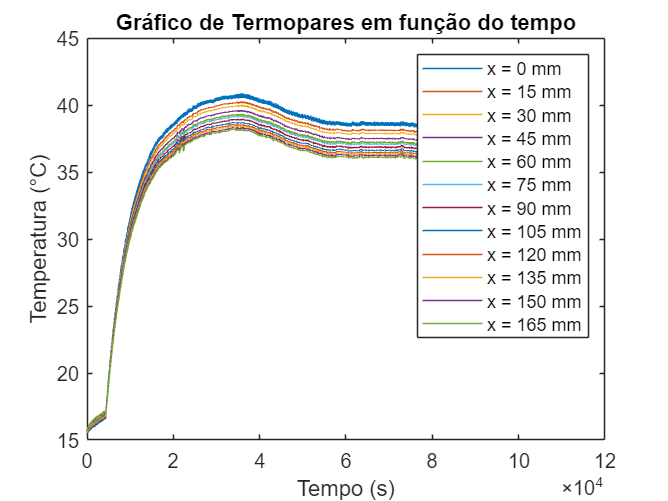

tamanho_time = length(time);
vetor_time = 10 * (0:tamanho_time-1);
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_time, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Tempo (s)');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do tempo');

% Gráfico 1.2
vetor_num_scan = data.ScanNumber

vetor_num_scan =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


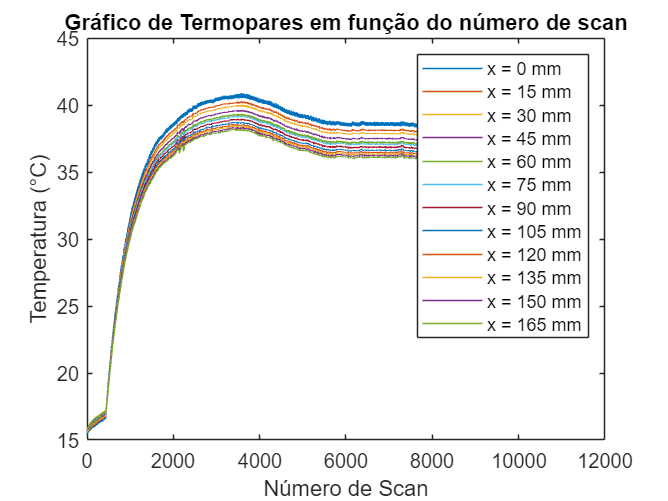

termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_num_scan, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Número de Scan');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do número de scan');

#### Intervalo do regime permanente identificado: Scan 6000 a 8000

% Filtrar as linhas que compõem o intervalo de regime permanente
regime_permanente = data((data.ScanNumber >= 6000) & (data.ScanNumber <= 8000), :);

% Selecionar as temperaturas não-NaN no intervalo filtrado
ind = ~isnan(regime_permanente.x101__C_);
Tamb_col = regime_permanente.x101__C_(ind);

% Calcular a temperatura média ambiente no intervalo
Tmamb = mean(Tamb_col);

% Calculando a temperatura média na aleta no regime permanente
Tm_aleta = 0;
termopares = {regime_permanente.x103__C_, regime_permanente.x104__C_, regime_permanente.x105__C_, regime_permanente.x106__C_, regime_permanente.x107__C_, regime_permanente.x108__C_, regime_permanente.x109__C_, regime_permanente.x110__C_, regime_permanente.x111__C_, regime_permanente.x112__C_, regime_permanente.x113__C_};

for i = 1: length(termopares)
    Tm_aleta = Tm_aleta + mean(termopares{i});
end

Tm_aleta = Tm_aleta/11;

% Temperatura de filme
Tf = (Tm_aleta + Tmamb)/2

Tf = 26.9225

% Calculando a condutividade do material no regime permanente (k), usando:
x0 = 37.76;
f_x0 = 155.68;

x1 = 51.67;
f_x1 = 156.88;

% Interpolacao de Newton:
%      f1(x) = f(x0) + (( f(x1) - f(x0) )   /  ( x1 - x0 )) * ( x - x0 )
k_Tf = f_x0 + ( ( f_x1 - f_x0 ) / (x1 - x0)) * (Tf - x0)

k_Tf = 154.7451